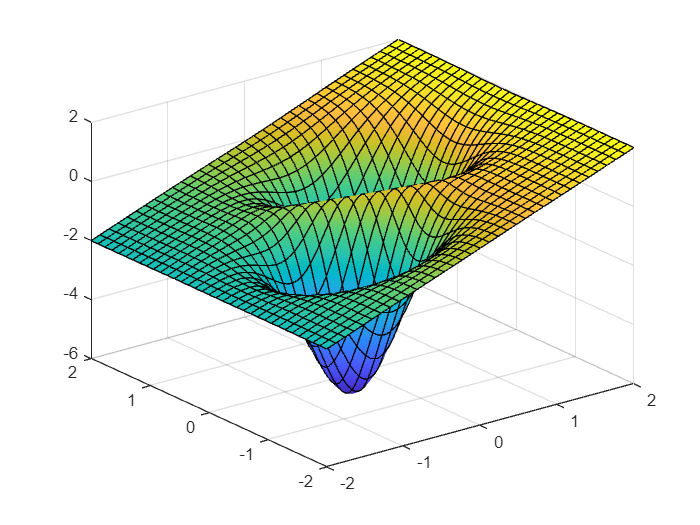

warning('off','all')
f =  @(x) x(1)-(4*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1)^2;
fsurf(@(x,y) x-(4*(x+y).*exp(-x.^2 - y.^2)+0.1)^2, [-2, 2, -2, 2])

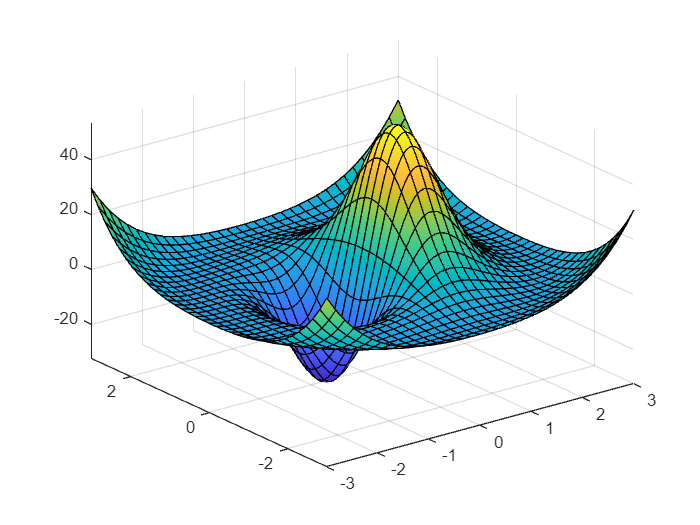


g = @(x) 0.3*x(1)+0.1*x(2)+(-3.5+0.5*x(1).^2+0.5*x(2).^2).^2+100*x(1).* exp(-x(1).^2 - x(2).^2);
fsurf(@(x, y) 0.3*x+0.1*y+(-3.5+0.5*x.^2+0.5*y.^2).^2+100*x .* exp(-x.^2 - y.^2), [-3, 3, -3, 3])

1. Minima Funkcji

n = 2;
Nmax = 1000;
P1 = [-1, -1];
P2 = [0, 0];
P3 = [3, 3];
P4 = [-0.8, 1];
P5 = [-2, -1];
d = eye(n);

[solution1, i1] = powell(P1, d, n, Nmax, f);
dis_min(P1, solution1, i1, f)

Dla punktu startowego: (-1, -1)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (-0.53333, -0.48905)
Wynik otrzymano w 7 iteracjach,
a wartość funkcji w tym punkcie wynosi: -5.9275
 



[solution2, i2] = powell(P2, d, n, Nmax, f);
dis_min(P2, solution2, i2, f)

Dla punktu startowego: (0, 0)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (0.46947, 0.51022)
Wynik otrzymano w 8 iteracjach,
a wartość funkcji w tym punkcie wynosi: -5.8966
 



[solution3, i3] = powell(P3, d, n, Nmax, f);
dis_min(P3, solution3, i3, f)

Dla punktu startowego: (3, 3)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (-4.017345110647492e+57, 4)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: -4.017345110647492e+57
 



[solution4, i4] = powell(P4, d, n, Nmax, f);
dis_min(P4, solution4, i4, f)

Dla punktu startowego: (-0.8, 1)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (0.46915, 0.51043)
Wynik otrzymano w 7 iteracjach,
a wartość funkcji w tym punkcie wynosi: -5.8966
 



[solution5, i5] = powell(P5, d, n, Nmax, f);
dis_min(P5, solution5, i5, f)

Dla punktu startowego: (-2, -1)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (0.46949, 0.51017)
Wynik otrzymano w 10 iteracjach,
a wartość funkcji w tym punkcie wynosi: -5.8966
 




[solution1, i1] = powell(P1, d, n, Nmax, g);
dis_min(P1, solution1, i1, g)

Dla punktu startowego: (-1, -1)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (-0.73727, -0.0012695)
Wynik otrzymano w 4 iteracjach,
a wartość funkcji w tym punkcie wynosi: -32.6112
 



[solution2, i2] = powell(P2, d, n, Nmax, g);

Przekroczono maksymalną liczbę iteracji.


dis_min(P2, solution2, i2, g)

Dla punktu startowego: (0, 0) nie znaleziono minimum
 



[solution3, i3] = powell(P3, d, n, Nmax, g);
dis_min(P3, solution3, i3, g)

Dla punktu startowego: (3, 3)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (-0.73729, -0.001264)
Wynik otrzymano w 23 iteracjach,
a wartość funkcji w tym punkcie wynosi: -32.6112
 



[solution4, i4] = powell(P4, d, n, Nmax, g);

Przekroczono maksymalną liczbę iteracji.


dis_min(P4, solution4, i4, g)

Dla punktu startowego: (-0.8, 1) nie znaleziono minimum
 



[solution5, i5] = powell(P5, d, n, Nmax, g);
dis_min(P5, solution5, i5, g)

Dla punktu startowego: (-2, -1)
punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (-0.73728, -0.0012695)
Wynik otrzymano w 4 iteracjach,
a wartość funkcji w tym punkcie wynosi: -32.6112
 



disp(' ')

disp('--------------------------------------------------')

--------------------------------------------------


2. Maksima Funkcji

f =  @(x) (-1)*(x(1)-(4*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1)^2);

g = @(x) (-1)*(0.3*x(1)+0.1*x(2)+(-3.5+0.5*x(1).^2+0.5*x(2).^2).^2+100*x(1).* exp(-x(1).^2 - x(2).^2));


[solution1, i1] = powell(P1, d, n, Nmax, f);
dis_max(P1, solution1, i1, f)

Dla punktu startowego: (-1, -1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (4.017345110647497e+57, 0)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 4.017345110647497e+57
 



[solution2, i2] = powell(P2, d, n, Nmax, f);
dis_max(P2, solution2, i2, f)

Dla punktu startowego: (0, 0)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (4.017345110647497e+57, 1)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 4.017345110647497e+57
 



[solution3, i3] = powell(P3, d, n, Nmax, f);
dis_max(P3, solution3, i3, f)

Dla punktu startowego: (3, 3)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (4.017345110647497e+57, 4)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 4.017345110647497e+57
 



[solution4, i4] = powell(P4, d, n, Nmax, f);
dis_max(P4, solution4, i4, f)

Dla punktu startowego: (-0.8, 1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (4.413587157693752e+56, 12.5)
Wynik otrzymano w 4 iteracjach,
a wartość funkcji w tym punkcie wynosi: 4.413587157693752e+56
 



[solution5, i5] = powell(P5, d, n, Nmax, f);
dis_max(P5, solution5, i5, f)

Dla punktu startowego: (-2, -1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (2.801496863426393e+57, 14.0789)
Wynik otrzymano w 6 iteracjach,
a wartość funkcji w tym punkcie wynosi: 2.801496863426393e+57
 




[solution1, i1] = powell(P1, d, n, Nmax, g);
dis_max(P1, solution1, i1, g)

Dla punktu startowego: (-1, -1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (0.68323, 0.0010742)
Wynik otrzymano w 4 iteracjach,
a wartość funkcji w tym punkcie wynosi: 53.7144
 



[solution2, i2] = powell(P2, d, n, Nmax, g);
dis_max(P2, solution2, i2, g)

Dla punktu startowego: (0, 0)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (0.6832, 0.0010742)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 53.7144
 



[solution3, i3] = powell(P3, d, n, Nmax, g);
dis_max(P3, solution3, i3, g)

Dla punktu startowego: (3, 3)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (4.017345110647497e+57, 4)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 6.511732844609373e+229
 



[solution4, i4] = powell(P4, d, n, Nmax, g);
dis_max(P4, solution4, i4, g)

Dla punktu startowego: (-0.8, 1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (0.68323, 0.0010742)
Wynik otrzymano w 4 iteracjach,
a wartość funkcji w tym punkcie wynosi: 53.7144
 



[solution5, i5] = powell(P5, d, n, Nmax, g);
dis_max(P5, solution5, i5, g)

Dla punktu startowego: (-2, -1)
punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (-4.017345110647492e+57, 0)
Wynik otrzymano w 2 iteracjach,
a wartość funkcji w tym punkcie wynosi: 6.511732844609341e+229
 


function [solution, i] = powell(x, d, n, Nmax, f)
    options = optimset('Display','none');
    X = {x};
    i = 1;
    cond = true;
    solution = nan;
    while cond
        p = {};
        p = [p, X(i)];
        for j = 1:n
            temp_d = d(:,j)';
            g = @(alfa) f([p{j}(1) + alfa*temp_d(1), p{j}(2) + alfa*temp_d(2)]);
            min_g = fminsearch(g, 1, options);
            new_p = p{j} + min_g*temp_d;
            p = [p, {new_p}];
        end
        
        if abs(f([p{n+1}(1), p{n+1}(2)]) - f([X{i}(1), X{i}(2)])) < 0.0001
            solution = p{n+1};
            return
        end
        
        for j = 1:n-1
            d(:,j) = d(:, j+1);
        end
        
        d(:,n) = (p{n}-p{1})';
        temp_d = d(:,n)';
        
        g = @(alfa) f([p{1}(1) + alfa*temp_d(1), p{1}(2) + alfa*temp_d(2)]);
        min_g = fminsearch(g, 1, options);
        new_x = p{1} + min_g*temp_d;    
        X = [X, {new_x}];
        i = i+1;
        
        cond = i < Nmax;
        if not (cond)
            solution = nan;
            disp('Przekroczono maksymalną liczbę iteracji.')
            return
        end
    end
end

function dis_min(P, solution, i, f)
    if not(isnan(solution))
        disp(['Dla punktu startowego: (', num2str(P(1)), ', ', num2str(P(2)), ')'])
        disp(['punkt w którym jest minimum funkcji, wyznaczony metodą Powella to: (', num2str(solution(1)), ', ', num2str(solution(2)), ')']);
        disp(['Wynik otrzymano w ', num2str(i), ' iteracjach,']);
        disp(['a wartość funkcji w tym punkcie wynosi: ', num2str(f(solution))]);
        disp(' ')
    else
        disp(['Dla punktu startowego: (', num2str(P(1)), ', ', num2str(P(2)), ') nie znaleziono minimum'])
        disp(' ')
    end
end

function dis_max(P, solution, i, f)
    if not(isnan(solution))
        disp(['Dla punktu startowego: (', num2str(P(1)), ', ', num2str(P(2)), ')'])
        disp(['punkt w którym jest maksimum funkcji, wyznaczony metodą Powella to: (', num2str(solution(1)), ', ', num2str(solution(2)), ')']);
        disp(['Wynik otrzymano w ', num2str(i), ' iteracjach,']);
        disp(['a wartość funkcji w tym punkcie wynosi: ', num2str((-1)*f(solution))]);
        disp(' ')
    else
        disp(['Dla punktu startowego: (', num2str(P(1)), ', ', num2str(P(2)), ') nie znaleziono maksimum'])
        disp(' ')
    end
end